local_repository  = 'D:/OvarianCD_PostQAQC/';
cancerFiles = dir([local_repository 'Cancer/*.txt'])

cancerFiles = 121×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


normalFiles = dir([local_repository 'Normal/*.txt'])

normalFiles = 95×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


files = [ strcat('Cancer/',{cancerFiles.name}) ...
          strcat('Normal/',{normalFiles.name})];
N = numel(files)   % total number of files

N = 216

type msbatchprocessing


function [MZ,Y] = msbatchprocessing(repository,files)
% MSBATCHPROCESSING Example function for BIODISTCOMPDEMO
%
% [MZ,Y] = MSBATCHPROCESSING(REPOSITORY,FILES) Preprocesses the
% spectrogram in files FILES and returns the mass/charge (MZ) and ion
% intensities (Y) vectors.
%
% Hard-coded parameters in the preprocessing steps have been adjusted to
% deal with the high-resolution spectrograms of the example.

% Copyright 2004-2013 The MathWorks, Inc.

K = numel(files);
Y = zeros(15000,K); % need to preset the size of Y for memory performance
MZ = zeros(15000,1);

parfor k = 1:K

    file = [repository files{k}]; 
    
    % read the two-column text file with mass-charge and intensity values
    fid = fopen(file,'r');
    ftext = textscan(fid, '%f%f');
    fclose(fid);
    signal = ftext{1};
    intensity = ftext{2};

    % resample the signal to 15000 points between 2000 and 11900
    mzout = (sqrt(2000)+(0:(15000-1))'*diff(sqrt([2000,11900]))/15000).^2;
    [mz,YR] = msresample(signal,

tic
repository = local_repository;
K = N; % change to N to do all

[MZ,Y] = msbatchprocessing(repository,files(1:K));

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.



disp(sprintf('Sequential time for %d spectrograms: %f seconds',K,toc))

Sequential time for 216 spectrograms: 377.624579 seconds


Y = msnorm(MZ,Y,'QUANTILE',0.5,'LIMITS',[3500 11000],'MAX',50);
grp = [repmat({'Cancer'},size(cancerFiles));...
       repmat({'Normal'},size(normalFiles))];
cancerIdx = find(strcmp(grp,'Cancer'));
numel(cancerIdx) % number of files in the "Cancer" subdirectory

ans = 121

normalIdx = find(strcmp(grp,'Normal'));
numel(normalIdx) % number of files in the "Normal" subdirectory

ans = 95

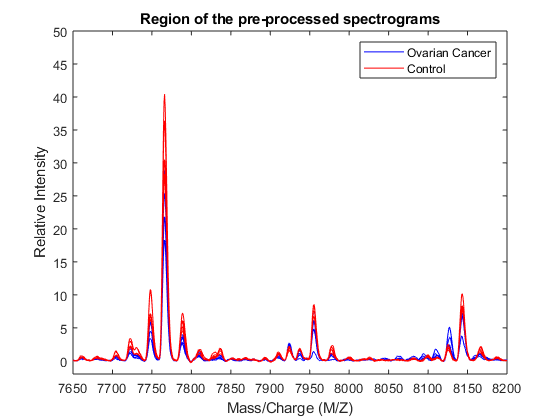

h = plot(MZ,Y(:,cancerIdx(1:5)),'b',MZ,Y(:,normalIdx(1:5)),'r');
axis([7650 8200 -2 50])
xlabel('Mass/Charge (M/Z)');ylabel('Relative Intensity')
legend(h([1 end]),{'Ovarian Cancer','Control'})
title('Region of the pre-processed spectrograms')

save OvarianCancerQAQCdataset.mat Y MZ grp